% Number of Monte Carlo experiments
numExperiments = 1;

% Arrays to store RMSE values for each experiment
Y_Chan_values  = zeros(numExperiments, 100);
Y_filter_values = zeros(numExperiments, 100);

for i = 1:numExperiments
    % Setup scenario with 3 receivers
    numReceivers = 3;
    [scenario, rxPairs] = helperCreateSingleTargetTDOAScenario(numReceivers);
    % Define accuracy in measurements
    measNoise = (100)^2; % ms^2
    
    % Display object
    display = HelperTDOATrackingExampleNoDisplay(XLimits=[-1e4 1e4],...
                                               YLimits=[-1e4 1e4],...
                                               LogAccuracy=true,...
                                               Title="Single Object Tracking");
    % Create a GNN tracker
    tracker = trackerGNN(FilterInitializationFcn=@helperInitHighSpeedKF,...
                         AssignmentThreshold=100);
    
    while advance(scenario)
        % Elapsed time
        time = scenario.SimulationTime;
    
        % Simulate TDOA detections without false alarms and missed detections
        tdoaDets = helperSimulateTDOA(scenario, rxPairs, measNoise);
    
        % Get estimated position and position covariance as objectDetection
        % objects
        posDet = helperTDOA2Pos(tdoaDets,true);
    
        % Update the tracker with position detections
        tracks = tracker(posDet, time);
    
        % Display results
        display(scenario, rxPairs, tdoaDets, {posDet}, tracks);
    end
    Y_Chan_values(i,:) = display.LoggedFusedMeasurementAccuracy;
    Y_filter_values(i,:) = display.LoggedTrackAccuracy;
end 

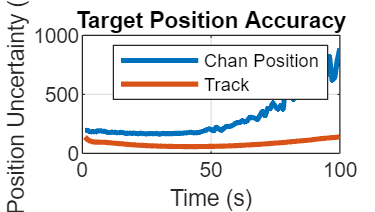

Y_Chan = sqrt(mean(Y_Chan_values.^2,1));
Y_filter = sqrt(mean(Y_filter_values.^2,1));

% PLot
f = figure('Units','normalized','Position',[0.1 0.1 0.6 0.6]);
ax = axes(f);
plot(ax,display.LoggedTime,Y_Chan,'LineWidth',2);
hold (ax, 'on');
plot(ax, display.LoggedTime,Y_filter,'LineWidth',2);
legend(ax, 'Chan Position','Track');
title(ax,'Target Position Accuracy');
xlabel(ax,'Time (s)');
ylabel(ax,'Position Uncertainty (m)');
grid(ax,'on');

## Supporting Functions

This section defines a few supporting functions used in this example. The complete list of helper functions can be found in the current working directory. 

`helperTDOA2Pos`

function varargout = helperTDOA2Pos(tdoaDets, reportDetection)
% This function uses the spherical intersection algorithm to find the
% object position from the TDOA detections assumed to be from the same
% object.
%
% This function assumes that all TDOAs are measured with respect to the
% same reference sensor. 
%
% [pos, posCov] = helperTDOA2Pos(tdoaDets) returns the estimated position
% and position uncertainty covariance.
%
% posDetection = helperTDOA2Pos(tdoaDets, true) returns the estimate
% position and uncertainty covariance as an objectDetection object. 

if nargin < 2
    reportDetection = false;
end

% Collect scaling information
params = helperGetGlobalParameters;
emissionSpeed = params.EmissionSpeed;
timeScale = params.TimeScale;

% Location of the reference receiver
referenceLoc = tdoaDets{1}.MeasurementParameters(2).OriginPosition(:);

% Formulate the problem. See [1] for more details
d = zeros(numel(tdoaDets),1);
delta = zeros(numel(tdoaDets),1);
S = zeros(numel(tdoaDets),3);
for i = 1:numel(tdoaDets)
    receiverLoc = tdoaDets{i}.MeasurementParameters(1).OriginPosition(:);
    d(i) = tdoaDets{i}.Measurement*emissionSpeed/timeScale;
    delta(i) = norm(receiverLoc - referenceLoc)^2 - d(i)^2;
    S(i,:) = receiverLoc - referenceLoc;
end

% Pseudo-inverse of S
Swstar = pinv(S);

% Assemble the quadratic range equation
STS = (Swstar'*Swstar);
a = 4 - 4*d'*STS*d;
b = 4*d'*STS*delta;
c = -delta'*STS*delta;

Rs = zeros(2,1);
% Imaginary solution, return a location outside coverage
if b^2 < 4*a*c 
    varargout{1} = 1e10*ones(3,1);
    varargout{2} = 1e10*eye(3);
    return;
end

% Two range values
Rs(1) = (-b + sqrt(b^2 - 4*a*c))/(2*a);
Rs(2) = (-b - sqrt(b^2 - 4*a*c))/(2*a);

% If one is negative, use the positive solution
if prod(Rs) < 0
    Rs = Rs(Rs > 0);
    pos = 1/2*Swstar*(delta - 2*Rs(1)*d) + referenceLoc;
else % Use range which minimize the error
    xs1 = 1/2*Swstar*(delta - 2*Rs(1)*d);
    xs2 = 1/2*Swstar*(delta - 2*Rs(2)*d);
    e1 = norm(delta - 2*Rs(1)*d - 2*S*xs1);
    e2 = norm(delta - 2*Rs(2)*d - 2*S*xs2);
    if e1  > e2
        pos = xs2 + referenceLoc;
    else
        pos = xs1 + referenceLoc;
    end
end

% If required, compute the uncertainty in the position
if nargout > 1 || reportDetection
    posCov = helperCalcPositionCovariance(pos,tdoaDets,timeScale,emissionSpeed);
end

if reportDetection
    varargout{1} = objectDetection(tdoaDets{1}.Time,pos,'MeasurementNoise',posCov);
else
    varargout{1} = pos;
    if nargout > 1
        varargout{2} = posCov;
    end
end

end

function measCov = helperCalcPositionCovariance(pos,thisDetections,timeScale,emissionSpeed)
n = numel(thisDetections);
% Complete Jacobian from position to N TDOAs
H = zeros(n,3);
% Covariance of all TDOAs
S = zeros(n,n);
for i = 1:n
   e1 = pos - thisDetections{i}.MeasurementParameters(1).OriginPosition(:);
   e2 = pos - thisDetections{i}.MeasurementParameters(2).OriginPosition(:);
   Htdoar1 = (e1'/norm(e1))*timeScale/emissionSpeed;
   Htdoar2 = (e2'/norm(e2))*timeScale/emissionSpeed;
   H(i,:) = Htdoar1 - Htdoar2;
   S(i,i) = thisDetections{i}.MeasurementNoise;
end
Pinv = H'/S*H;
% Z is not measured, use 1 as the covariance
if Pinv(3,3) < eps
    Pinv(3,3) = 1;
end

% Insufficient information in TDOA
if rank(Pinv) >= 3
    measCov = eye(3)/Pinv;
else
    measCov = inf(3);
end

% Replace inf with large number
measCov(~isfinite(measCov)) = 100;

% Return a true symmetric, positive definite matrix for covariance.
measCov = (measCov + measCov')/2;
end

`helperInitHighSpeedKF`

function filter = helperInitHighSpeedKF(detection)
% This function initializes a constant velocity Kalman filter and sets a
% higher initial state covariance on velocity components to account for
% high speed of the object vehicles. 
filter = initcvukf(detection);
filter.StateCovariance(2:2:end,2:2:end) = 500*eye(3);
end

`helperTOA2Pos`

function [posTime, posTimeCov] = helperTOA2Pos(toaDetections)
% This function computes the position and emission time of a target given
% its time-of-arrival detections from multiple receivers. 
%

% Convert TOAs to TDOAs for using spherical intersection
[tdoaDetections, isValid] = helperTOA2TDOADetections(toaDetections);

% At least 3 TOAs (2 TDOAs) required. Some TOA pairings can lead to an
% invalid TDOA (> maximum TDOA). In those situations, discard the tuple by
% using an arbitrary position with a large covariance.
if numel(tdoaDetections) < 2 || any(~isValid)
    posTime = 1e10*ones(4,1);
    posTimeCov = 1e10*eye(4);
else
    % Get position estimate using TDOA fusion. 
    % Get time estimate using calculated position.
    if nargout > 1 % Only calculate covariance when requested to save time
        [pos, posCov] = helperTDOA2Pos(tdoaDetections);
        [time, timeCov] = helperCalcEmissionTime(toaDetections, pos, posCov);
        posTime = [pos;time];
        posTimeCov = blkdiag(posCov,timeCov);
    else
        pos = helperTDOA2Pos(tdoaDetections);
        time = helperCalcEmissionTime(toaDetections, pos);
        posTime = [pos;time];
    end
end
end

**helperCalcEmissionTime**

function [time, timeCov] = helperCalcEmissionTime(toaDetections, pos, posCov)
% This function calculates the emission time of an object given its
% position and obtained TOA detections. It also computes the uncertainty in
% the estimate time. 
globalParams = helperGetGlobalParameters;
emissionSpeed = globalParams.EmissionSpeed;
timeScale = globalParams.TimeScale;
n = numel(toaDetections);
emissionTime = zeros(n,1);
emissionTimeCov = zeros(n,1);
for i = 1:numel(toaDetections)
    % Calculate range from this receiver
    p0 = toaDetections{i}.MeasurementParameters.OriginPosition(:);
    r = norm(pos - p0);
    emissionTime(i) = toaDetections{i}.Measurement - r/emissionSpeed*timeScale;
    if nargout > 1
        rJac = (pos - p0)'/r;
        rCov = rJac*posCov*rJac';
        emissionTimeCov(i) = rCov./emissionSpeed^2*timeScale^2;
    end
end
% Gaussian merge each time and covariance estimate
time = mean(emissionTime);
if nargout > 1
    e = emissionTime - time;
    timeCov = mean(emissionTimeCov) + mean(e.^2);
end
end

`helperMeasureTOA`

function toa = helperMeasureTOA(posTime, params)
% This function calculates the expected TOA at a receiver given an object
% position and emission time and the receiver's measurement parameters
% (OriginPosition)
globalParams = helperGetGlobalParameters;
emissionSpeed = globalParams.EmissionSpeed;
timeScale = globalParams.TimeScale;
r = norm(posTime(1:3) - params.OriginPosition);
toa = posTime(4) + r/emissionSpeed*timeScale;
end

`helperMeasureTDOA`

function toa = helperMeasureTDOA(pos, params)
% This function calculates the expected TDOA measurement given object
% position and measurement parameters of a TDOA detection
globalParams = helperGetGlobalParameters;
emissionSpeed = globalParams.EmissionSpeed;
timeScale = globalParams.TimeScale;
r1 = norm(pos(1:3) - params(1).OriginPosition);
r2 = norm(pos(1:3) - params(2).OriginPosition);
toa = (r1 - r2)/emissionSpeed*timeScale;
end

Copyright 2021 The MathWorks, Inc. 